# Projekt 2

### Zadanie 1:

clear;
disp('Zadanie 1:')

Zadanie 1:


symulacja_obiektu15y_p2(0,0,0,0,0,0)

ans = 0

SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
fig = stairs(Y)

fig =   Stair with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×500 double]
              YData: [1×500 double]

  Show all properties


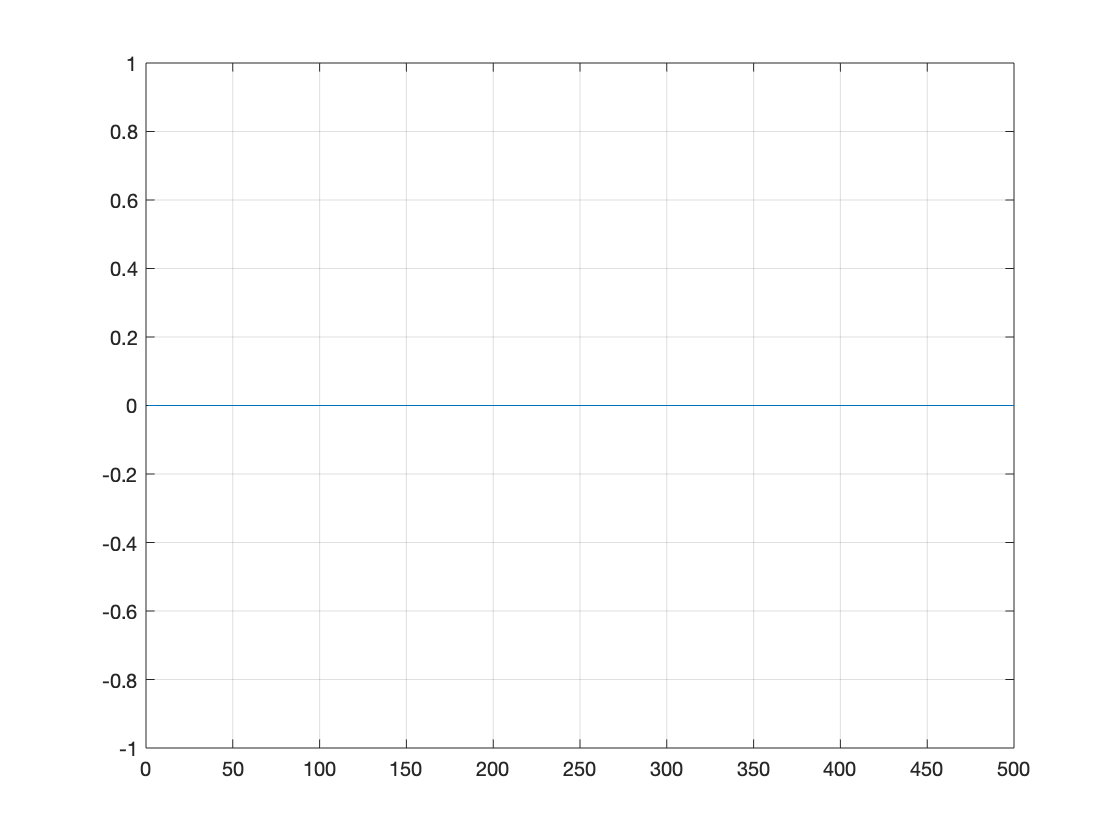

grid


writematrix([fig.XData; fig.YData]', 'txts/p2_zadanie1.txt', "Delimiter","tab")

### Zadanie 2:

clear;
disp('Zadanie 2:')

Zadanie 2:


Tor wejście wyjście

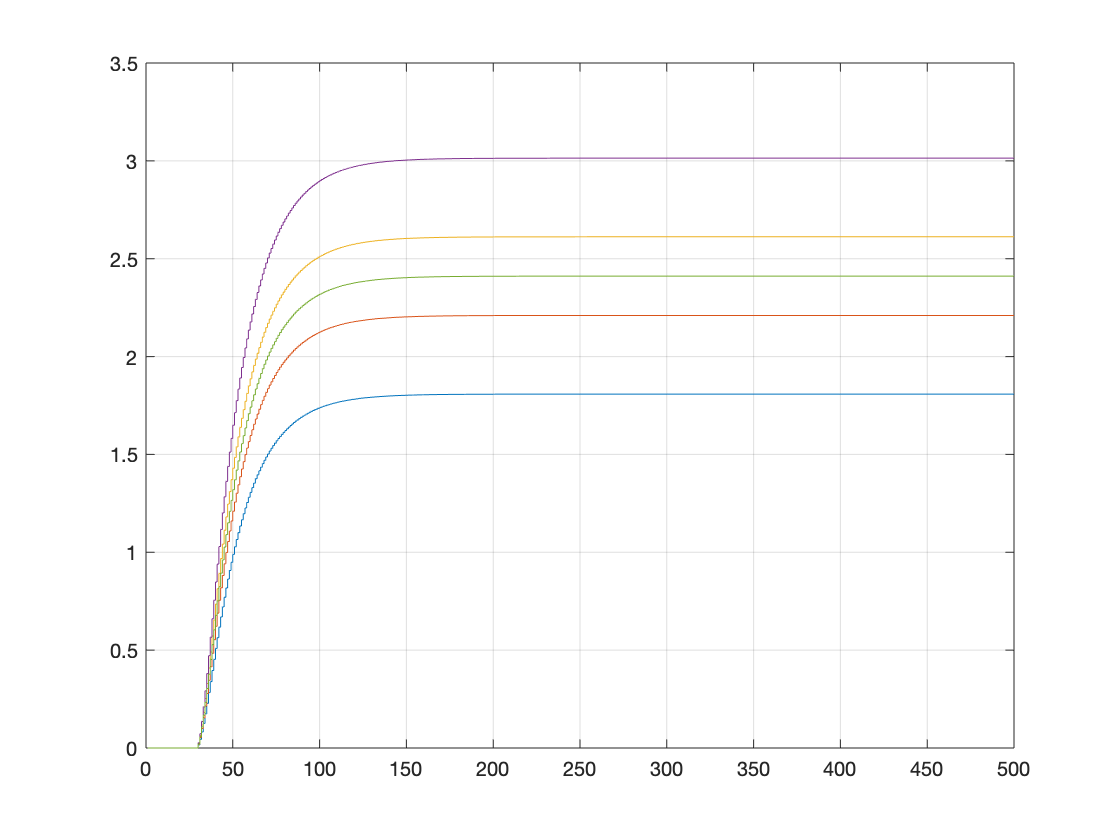

U_zad_zmiany = [0.9, 1.1, 1.3, 1.5, 1.2];
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 10;

for p=1:length(U_zad_zmiany)
    U(STEP_MOMENT:end) = U_zad_zmiany(p);
    for k=30:SIM_LENGHT
        Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
            U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Tor zakłócenie-wyjście

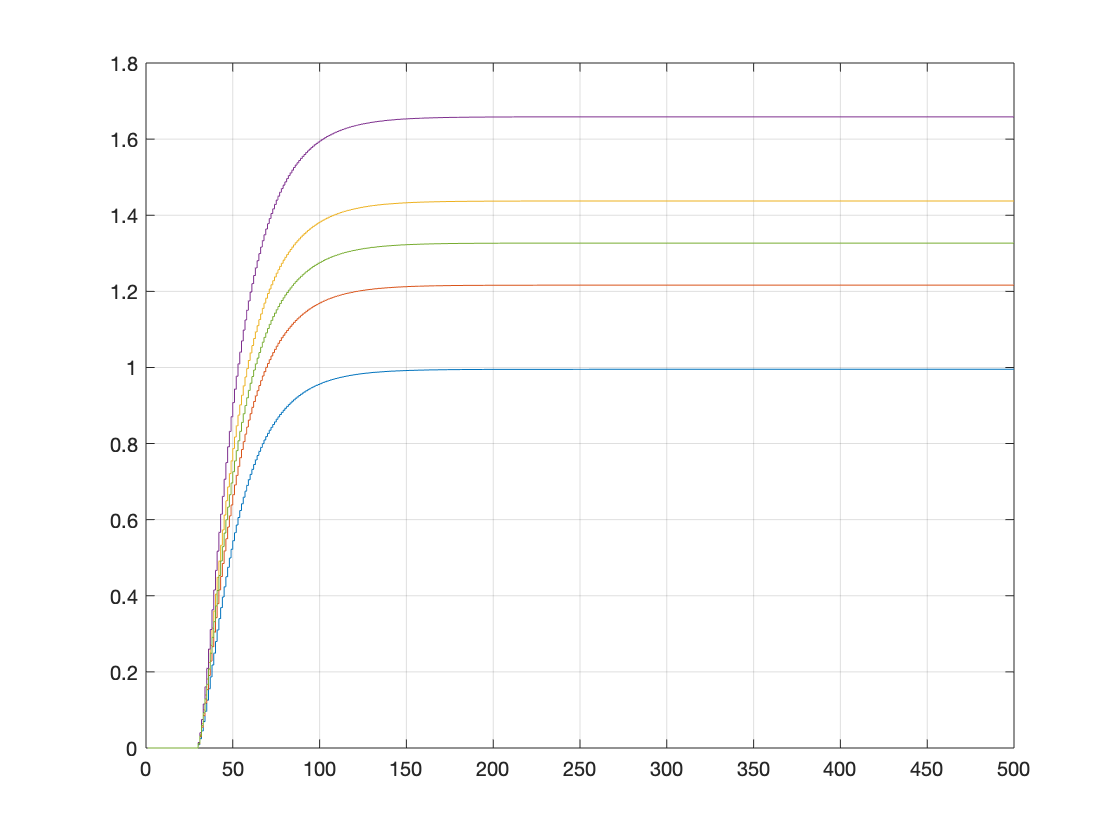

Z_zad_zmiany = [0.9, 1.1, 1.3, 1.5, 1.2];
SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 10;

for p=1:length(U_zad_zmiany)
    Z(STEP_MOMENT:end) = Z_zad_zmiany(p);
    for k=30:SIM_LENGHT
        Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
            U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Narysować charakterystykę statyczną procesu *y*(*u,z*). Czy właściwo- ści statyczne i dynamiczne procesu są (w przybliżeniu) liniowe? Jeżeli tak, określić wzmocnienie statyczne obu torów procesu. 	 

disp('Charakterystyka statyczna:')

Charakterystyka statyczna:


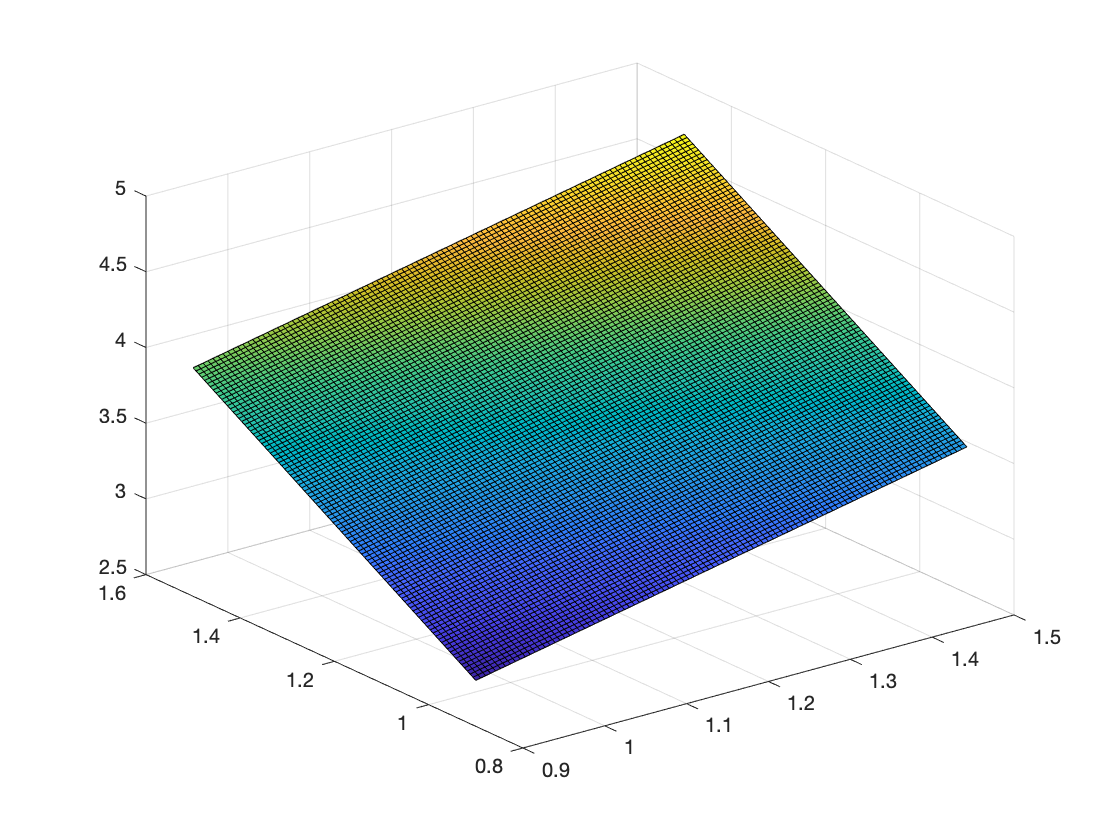

dim = 100;
Y_stat = zeros(dim,dim);

U_zad = linspace(0.9, 1.5, dim)';
Z_zad = linspace(0.9, 1.5, dim)';
X = NaN(dim*dim,3);
for i = 1:length(U_zad)
    for j = 1:length(Z_zad)
      [Y, U, Z] = get_YUZ(U_zad(i),Z_zad(j), SIM_LENGHT, STEP_MOMENT);
      Y_stat(i,j)= Y(SIM_LENGHT);  
      X(100*(i-1)+j,:)=[1,U_zad(i),Z_zad(j)];
    end
    
end
% plot(U_zad, Y_stat)
surf(U_zad, Z_zad, Y_stat)

Wzmocnienie statyczne to wspolczynnik kierunkowy prostej z wykresu

    x = U_zad(:);
    y = Y_stat(:);

    b = (X'*X)\X'*y;
    gain_u = b(2)

gain_u = 1.1057

    gain_z = b(3)

gain_z = 2.0092

### Zadanie 3:

Wyznaczyć odpowiedzi skokowe obu torów wykorzystywane w algorytmie DMC, tzn. zestaw liczb *s*1*, s*2*, . . . *oraz *s*z1*, s*z2*, . . . *(przy skoku jednostkowym, odpowiednio sygnału sterującego i zakłócającego: od chwili *k *= 0 włącznie sygnał wymuszenia ma wartość 1, w przeszłości jest zerowy). Zamieścić rysunki odpowiedzi skokowych obu torów 

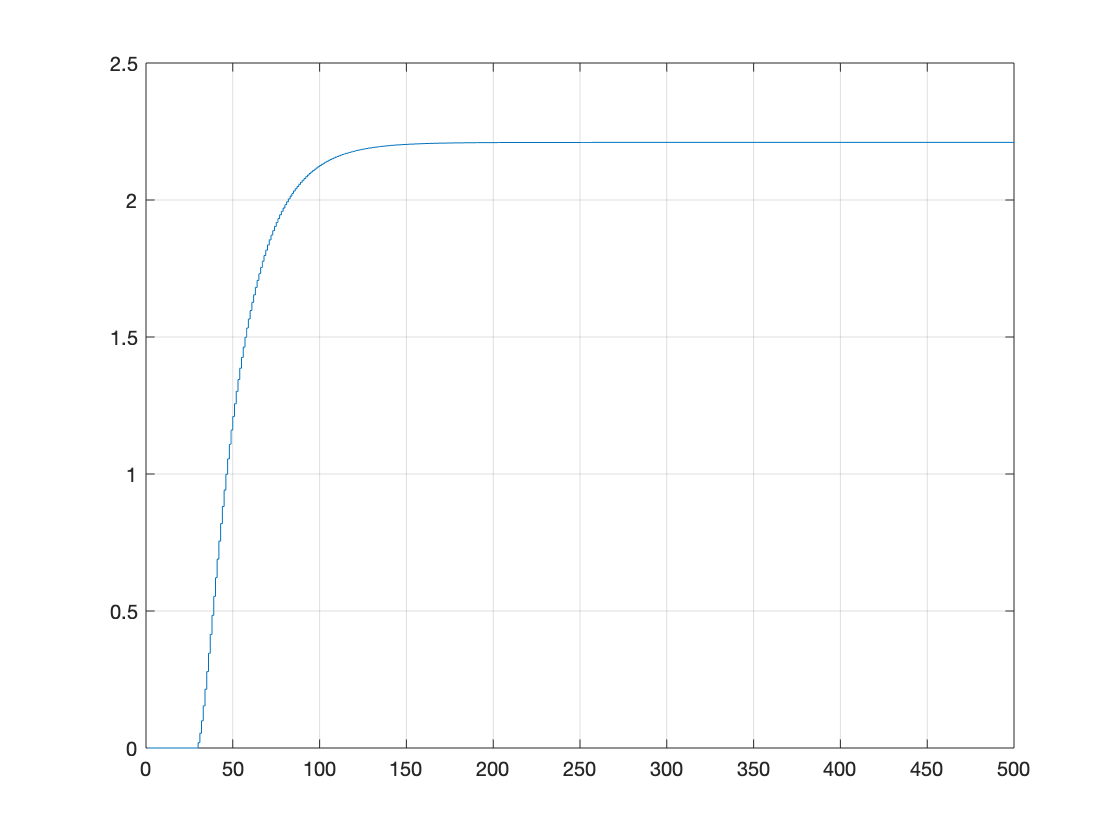

SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 10;

U(STEP_MOMENT:end) = 1.1;
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
stairs(Y)
grid on

Tor zakłócenie-wyjście

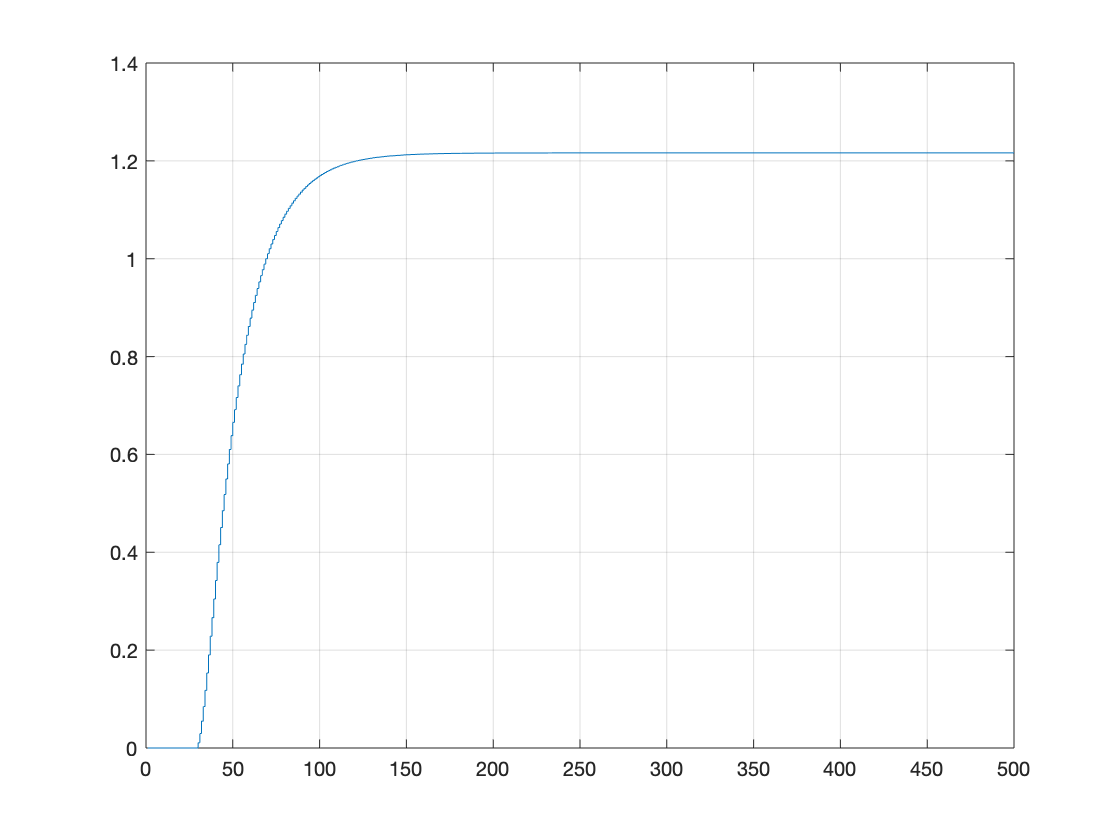

SIM_LENGHT = 500;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
Z = zeros(SIM_LENGHT,1);

STEP_MOMENT = 10;

Z(STEP_MOMENT:end) = 1.1;
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
stairs(Y)
grid on

#### FUNKCJE:

Funkcja Piotra do wyznaczania odpowiedzi skokowych

function [Y, U, Z] = get_YUZ(U_zad,Z_zad, sim_lenght, step_moment)
Y = zeros(sim_lenght,1);
U = zeros(sim_lenght,1);
Z = zeros(sim_lenght,1);
U(step_moment:end) = U_zad;
Z(step_moment:end) = Z_zad;
for k=30:sim_lenght
    Y(k) = symulacja_obiektu15y_p2(U(k-6), ...
        U(k-7),Z(k-3),Z(k-4), Y(k-1), Y(k-2));
end
end
